Controllo se è rimasta aperta la porta seriale

if( exist('STM32_ser') );
    delete(STM32_ser);
    clear STM32_ser;
end

Connetto alla seriale

porte_libere = serialportlist("available")

porte_libere = "COM8"

STM32_ser = serialport(porte_libere(end), 1000000, Timeout=2);
configureTerminator(STM32_ser,"CR");

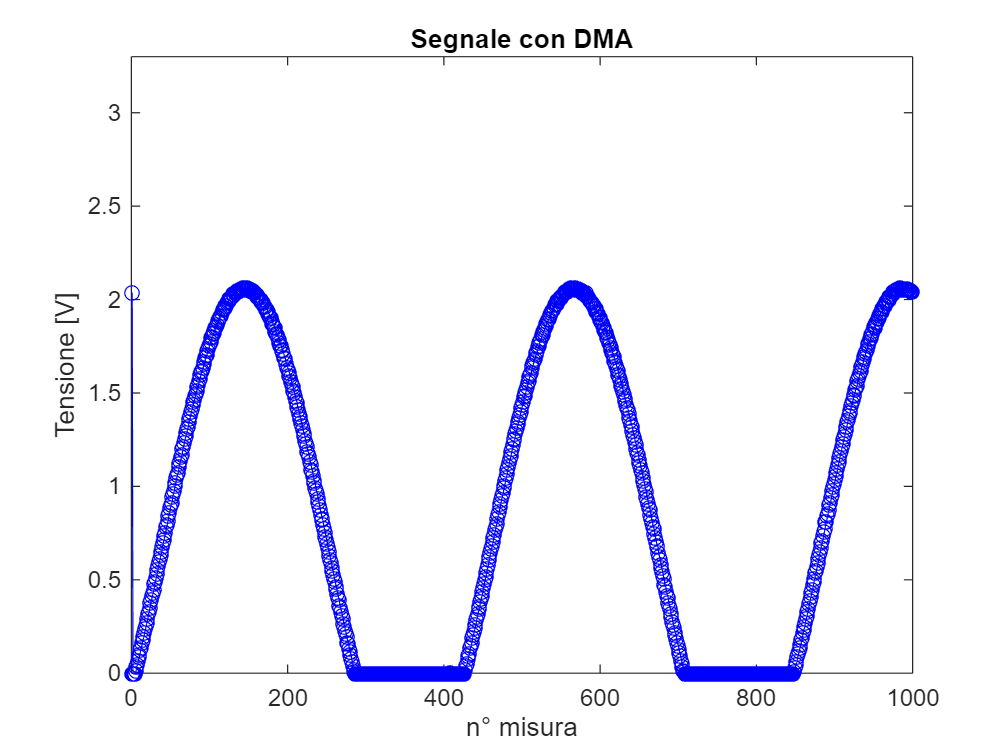

buff_size = 1000 + 1;
f = figure(1);

while 1
    STM32_ser.flush;
    STM32_ser.write('?','char');
    buff_data = STM32_ser.read(buff_size,'uint16');
    
    tr_index = buff_data(end);
    
    buff_data = buff_data(1:end-1);
    buff_data = circshift(buff_data, tr_index);
    buff_data = buff_data ./ 2^16 * 3.3;
    
    f = figure(1);
    plot(1:length(buff_data), buff_data, 'b-o');
    
    title("Segnale con DMA");
    xlabel("n° misura");
    ylabel("Tensione [V]");
    ylim([0,3.3]);
end